Answer the following questions for any of the bimatrix games reported below:

a) Find strictly dominated strategies (if any) and reduce the cost matrices accordingly.

b) Do pure strategies Nash equilibria exist?

c) Find all the mixed strategies Nash equilibria of the game by solving the related KKT system.

e) Find the best response mapping of each player and find all the mixed strategies Nash equilibria.

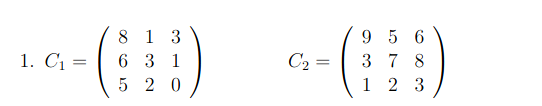

close all;
clear;
clc;

syms x y x1 x2 x3 y1 y2 y3 mu1 mu2

C1 = [8 1 3
      6 3 1
      5 2 0]

C1 =      8     1     3
     6     3     1
     5     2     0



C2 = [9 5 6
      3 7 8
      1 2 3]

C2 =      9     5     6
     3     7     8
     1     2     3



Cr1 = [8 3
       6 1]

Cr1 =      8     3
     6     1



Cr2 = [9 6
       3 8]

Cr2 =      9     6
     3     8



x = [x1 
     x2 
     x3];

y = [y1
     y2
     y3];

equation = [ C1*y + mu1 >= 0
             C2'*x + mu2 >= 0
             x.*(C1*y + mu1) == 0
             y.*(C2'*x + mu2) == 0
             x >= 0
             y >= 0
             x1 + x2 + x3 == 1
             y1 + y2 + y3 == 1]

$$equation = \begin{array}{l} \left(\begin{array}{c} 0\leq \sigma_{3}\\ 0\leq \sigma_{4}\\ 0\leq \sigma_{6}\\ 0\leq \sigma_{5}\\ 0\leq \sigma_{2}\\ 0\leq \sigma_{1}\\ x_{1}\,\sigma_{3}=0\\ x_{2}\,\sigma_{4}=0\\ x_{3}\,\sigma_{6}=0\\ y_{1}\,\sigma_{5}=0\\ y_{2}\,\sigma_{2}=0\\ y_{3}\,\sigma_{1}=0\\ 0\leq x_{1}\\ 0\leq x_{2}\\ 0\leq x_{3}\\ 0\leq y_{1}\\ 0\leq y_{2}\\ 0\leq y_{3}\\ x_{1}+x_{2}+x_{3}=1\\ y_{1}+y_{2}+y_{3}=1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mu_{2}+6\,x_{1}+8\,x_{2}+3\,x_{3}\\ \sigma_{2}=\mu_{2}+5\,x_{1}+7\,x_{2}+2\,x_{3}\\ \sigma_{3}=\mu_{1}+8\,y_{1}+y_{2}+3\,y_{3}\\ \sigma_{4}=\mu_{1}+6\,y_{1}+3\,y_{2}+y_{3}\\ \sigma_{5}=\mu_{2}+9\,x_{1}+3\,x_{2}+x_{3}\\ \sigma_{6}=\mu_{1}+5\,y_{1}+2\,y_{2} \end{array}$$

% Compute analytic solution of a symbolic equation
solution2 = solve(equation,[x1,x2,x3,y1,y2,y3,mu1,mu2]);
% Display symbolic solution returned by solve
displaySymSolution(solution2);

solution2 = struct with fields:
     x1: [3×1 sym]
     x2: [3×1 sym]
     x3: [3×1 sym]
     y1: [3×1 sym]
     y2: [3×1 sym]
     y3: [3×1 sym]
    mu1: [3×1 sym]
    mu2: [3×1 sym]


where


$$\left(\begin{array}{cccccccc} x_{1}\left(1\right) & x_{2}\left(1\right) & x_{3}\left(1\right) & y_{1}\left(1\right) & y_{2}\left(1\right) & y_{3}\left(1\right) & \mu_{1}\left(1\right) & \mu_{2}\left(1\right) \end{array}\right)=\left(\begin{array}{cccccccc} 1 & 0 & 0 & 0 & 1 & 0 & -1 & -5 \end{array}\right)$$

$$\left(\begin{array}{cccccccc} x_{1}\left(2\right) & x_{2}\left(2\right) & x_{3}\left(2\right) & y_{1}\left(2\right) & y_{2}\left(2\right) & y_{3}\left(2\right) & \mu_{1}\left(2\right) & \mu_{2}\left(2\right) \end{array}\right)=\left(\begin{array}{cccccccc} 0 & 0 & 1 & 1 & 0 & 0 & -5 & -1 \end{array}\right)$$

$$\left(\begin{array}{cccccccc} x_{1}\left(3\right) & x_{2}\left(3\right) & x_{3}\left(3\right) & y_{1}\left(3\right) & y_{2}\left(3\right) & y_{3}\left(3\right) & \mu_{1}\left(3\right) & \mu_{2}\left(3\right) \end{array}\right)=\left(\begin{array}{cccccccc} \frac{1}{5} & 0 & \frac{4}{5} & \frac{1}{4} & \frac{3}{4} & 0 & -\frac{11}{4} & -\frac{13}{5} \end{array}\right)$$


variables = [x
             y
             mu1
             mu2]

$$variables = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ y_{1}\\ y_{2}\\ y_{3}\\ \mu_{1}\\ \mu_{2} \end{array}\right)$$


solution = solve(equation, variables)

solution = struct with fields:
     x1: [3×1 sym]
     x2: [3×1 sym]
     x3: [3×1 sym]
     y1: [3×1 sym]
     y2: [3×1 sym]
     y3: [3×1 sym]
    mu1: [3×1 sym]
    mu2: [3×1 sym]




% Existence of Pure Nash Equilibrium (x1,y1) = (8,9)
% Nash Equilibrium


$$\left(\begin{array}{cccccccc}
x_1 \left(1\right) & x_2 \left(1\right) & x_3 \left(1\right) & y_1 \left(1\right) & y_2 \left(1\right) & y_3 \left(1\right) & \mu_1 \left(1\right) & \mu_2 \left(1\right)
\end{array}\right)=\left(\begin{array}{cccccccc}
1 & 0 & 0 & 0 & 1 & 0 & -1 & -5
\end{array}\right)$$



$$\left(\begin{array}{cccccccc}
x_1 \left(2\right) & x_2 \left(2\right) & x_3 \left(2\right) & y_1 \left(2\right) & y_2 \left(2\right) & y_3 \left(2\right) & \mu_1 \left(2\right) & \mu_2 \left(2\right)
\end{array}\right)=\left(\begin{array}{cccccccc}
0 & 0 & 1 & 1 & 0 & 0 & -5 & -1
\end{array}\right)$$



$$\left(\begin{array}{cccccccc}
x_1 \left(3\right) & x_2 \left(3\right) & x_3 \left(3\right) & y_1 \left(3\right) & y_2 \left(3\right) & y_3 \left(3\right) & \mu_1 \left(3\right) & \mu_2 \left(3\right)
\end{array}\right)=\left(\begin{array}{cccccccc}
\frac{1}{5} & 0 & \frac{4}{5} & \frac{1}{4} & \frac{3}{4} & 0 & -\frac{11}{4} & -\frac{13}{5}
\end{array}\right)$$




% Dominance

Player 1

Strategy 3 is dominated by Strategy 2. 

Player 2

Strategy 2 is dominated by Strategy 3

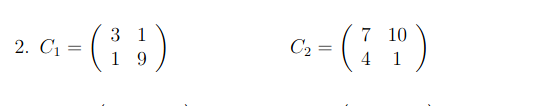

close all;
clear;
clc;


C1 = [3 1
      1 9]

C1 =      3     1
     1     9



C2 = [7 10
      4 1]

C2 =      7    10
     4     1


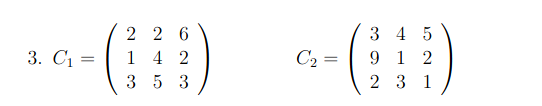

close all;
clear;
clc;


C1 = [2 2 6
      1 4 2
      3 5 3]

C1 =      2     2     6
     1     4     2
     3     5     3



C2 = [3 4 5
      9 1 2
      2 3 1] 

C2 =      3     4     5
     9     1     2
     2     3     1


close all;
clear;
clc;


C1 = [1 6
      8 3]

C1 =      1     6
     8     3



C2 = [1 4
      4 1]

C2 =      1     4
     4     1


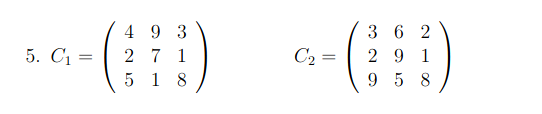

close all;
clear;
clc;


C1 = [4 9 3
      2 7 1
      5 1 8]

C1 =      4     9     3
     2     7     1
     5     1     8



C2 = [3 6 2
      2 9 1
      9 5 8]  

C2 =      3     6     2
     2     9     1
     9     5     8


close all;
clear;
clc;


C1 = [3 1
      2 2]

C1 =      3     1
     2     2



C2 = [1 3
      4 3]

C2 =      1     3
     4     3
